# Exercise 7

clear all; close all; clc;

## Problem 1

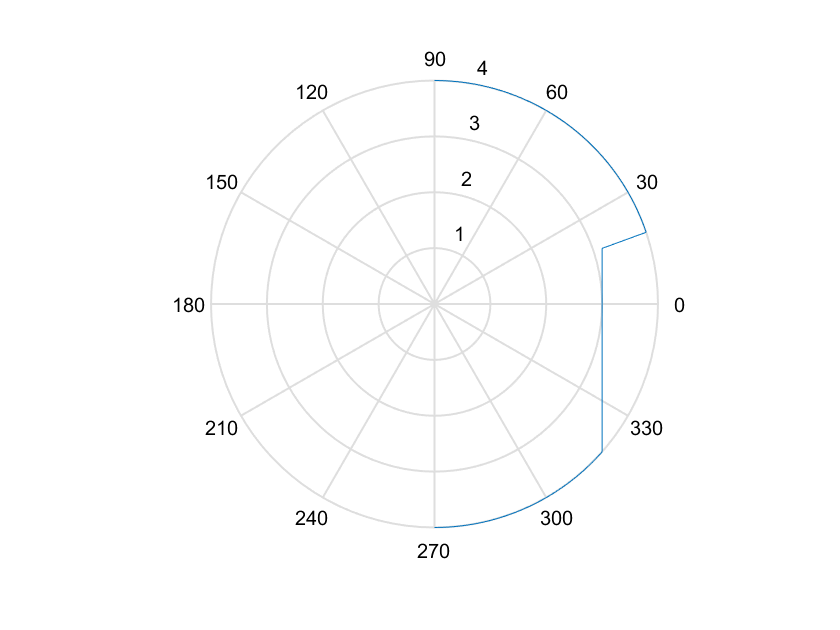

lines = [3; -4; 3; 1];
pose = [0;0;0];
maxDistance=4;
resol=0.36;
field_of_view=180;
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
polar(scan(1,:), scan(2,:));

## Problem 2

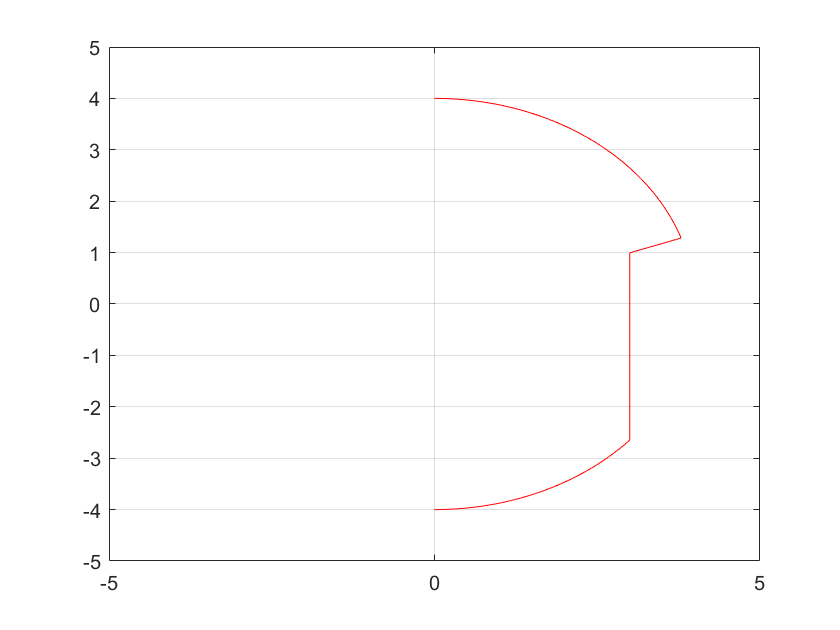

car = polar2carth(scan);
plot(car(1,:), car(2,:),'r');
set(gca, 'xlim', [-5, 5], 'ylim', [-5, 5]);
grid on;
box on;

## Problem 3

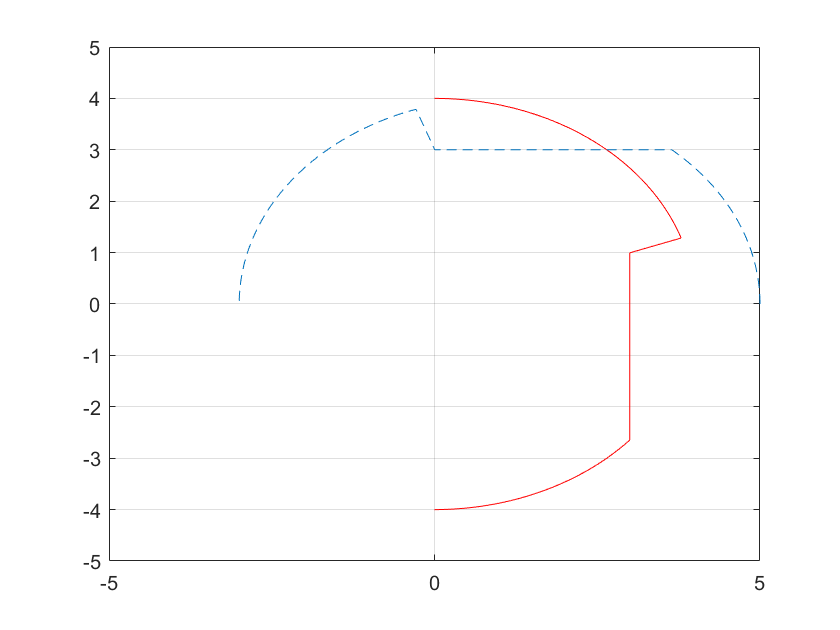

pos_l = [car;scan(1,:)];
pose = [1;0;pi/2];
pos_w = transform(pose, pos_l);
hold on;
plot(pos_w(1,:), pos_w(2,:), '--');
hold off;

## Problem 4

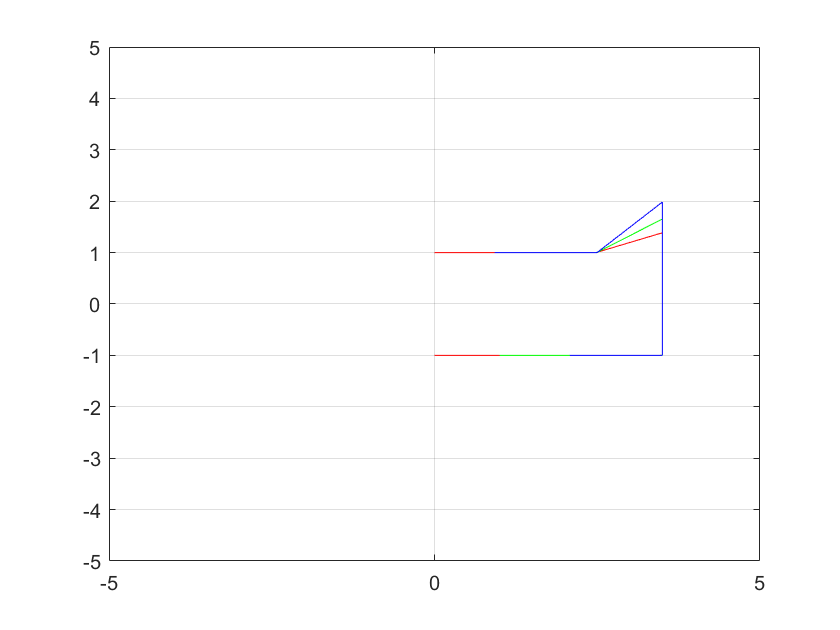

lines = [0,2.5,0,3.5; 1,1,-1,-1; 2.5,2.5,3.5,3.5; 1,5,-1,5];
maxDistance=4;
resol=0.36;
field_of_view=180;
pose = [0;0;0];
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
car = polar2carth(scan);
pos_w = transform(pose, [car;scan(1,:)]);
figure;
plot(pos_w(1,:), pos_w(2,:),'r');
set(gca, 'xlim', [-5, 5], 'ylim', [-5, 5]);
grid on;
box on;
hold on;
pose = [1;0;0];
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
car = polar2carth(scan);
pos_w = transform(pose, [car;scan(1,:)]);
plot(pos_w(1,:), pos_w(2,:),'g');
hold on;
pose = [1.5;0;pi/6];
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
car = polar2carth(scan);
pos_w = transform(pose, [car;scan(1,:)]);
plot(pos_w(1,:), pos_w(2,:),'b');
hold off;

## Problem 5

line = isqline([5,5,5,5,5,5,5;1,2,3,4,5,6,7])

line =      0     5


line = isqline([1,2,3,4,5,6,7;3,3,3,3,3,3,3])

line =     1.5708    3.0000


x = linspace(1,10);
y = -x-3;
line = isqline([x;y])

line =     0.7854    2.1213


## Problem 6

p1 = [0,1,2.5;1,1,1];
p2 = [3.5,3.5,3.5;-1,0,5];
p3 = [0,1,2,3.5;-1.05,-1,-1,-1];
line = isqline(p1)
line = isqline(p2)
line = isqline(p3)

line =    -1.5586    1.0322


## Problem 7

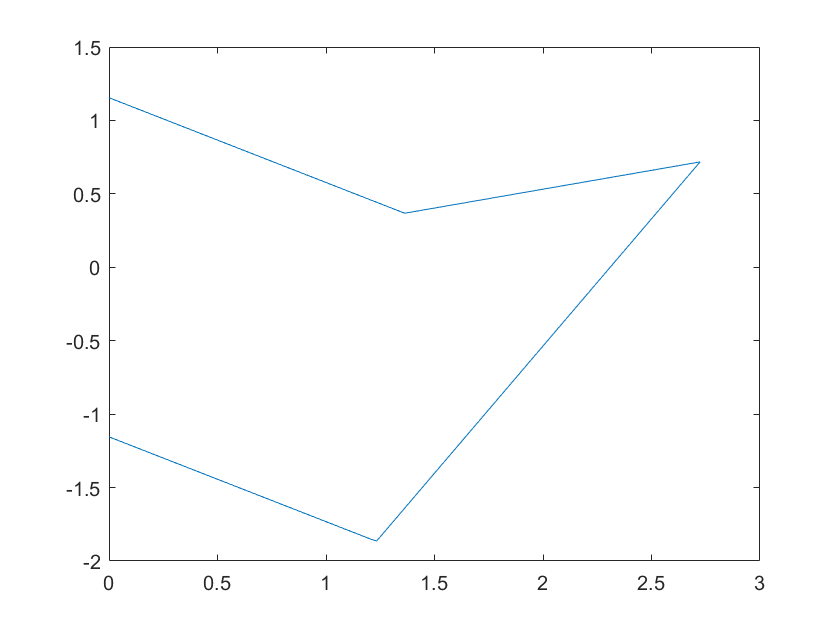

lines = [0,2.5,0,3.5; 1,1,-1,-1; 2.5,2.5,3.5,3.5; 1,5,-1,5];
maxDistance=4;
resol=0.36;
field_of_view=180;
pose = [1.5;0;pi/6];
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
car = polar2carth(scan);
plot(car(1,:),car(2,:));

p1 = [0.01,0.73,1.14;1.15,0.7,0.5];
p2 = [2.5843,1.835,1.4775;0.47618,-0.82162,-1.4409];
p3 = [0.25,0.5,0.73;-1.3,-1.44,-1.576];
line = isqline(p1)

line =     1.0441    0.9922


line = isqline(p2)

line =    -0.5236    2.0000


line = isqline(p3)

line =     1.0491    1.0014


## Problem 8

lines = [0,2.5,0,3.5; 1,1,-1,-1; 2.5,2.5,3.5,3.5; 1,5,-1,5];
maxDistance=4;
resol=0.36;
field_of_view=180;
pose = [1.5;0;pi/6];
scan = laserscan2011(pose(1),pose(2),pose(3),lines, maxDistance,resol, field_of_view);
car = polar2carth(scan);
plot(car(1,:),car(2,:));

p1 = [0.0144,0.73205,1.1432;1.1464,0.73205,0.49469];
p2 = [2.5843,1.835,1.4775;0.47618,-0.82162,-1.4409];
p3 = [0.24753,0.49906,0.72949;-1.2976,-1.4428,-1.5759];
line = isqline(p1);
line = transLine(line(1), line(2), pose(1), pose(2), pose(3))

line =     1.5708
    1.0000


line = isqline(p2);
line = transLine(line(1), line(2), pose(1), pose(2), pose(3))

line =     0.0000
    3.5000


line = isqline(p3);
line = transLine(line(1), line(2), pose(1), pose(2), pose(3))

line =     1.5707
    1.0000
